[[小练习]有限磁场下的BCS超导体 - 知乎](https://zhuanlan.zhihu.com/p/13493633949)

% main program

clc; clear;

% 参数结构体
params.t = 1;
params.t1 = -0.0 * params.t;
params.t2 = 0.0 * params.t;
params.g = 4.0 * params.t;
params.nc = 0.6;
params.T = 0.5 * params.t;
params.B = 0.66;

tic
x0 = [0.5, -1];
options = optimset('Display', 'iter', 'MaxFunEvals', 40);
[x, fval] = fsolve(@(A) F1(A, params), x0, options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3          0.00674424                          0.0227              1
     1          6         0.000428475       0.537673         0.000373              1
     2          7         0.000428475        1.34418         0.000373           1.34
     3          8         0.000428475       0.336046         0.000373          0.336
     4          9         0.000428475      0.0840114         0.000373          0.084
     5         12         0.000426074      0.0210029         1.48e-05          0.021
     6         13         0.000426074      0.0210029         1.48e-05          0.021
     7         14         0.000426074     0.00525071         1.48e-05        0.00525
     8         17         0.000426058     0.00131268         3.97e-06        0.00131
     9         20         0.000426053     0.00131268         3.4

x

x =    -0.0000   -1.2343


toc

历时 0.271871 秒。


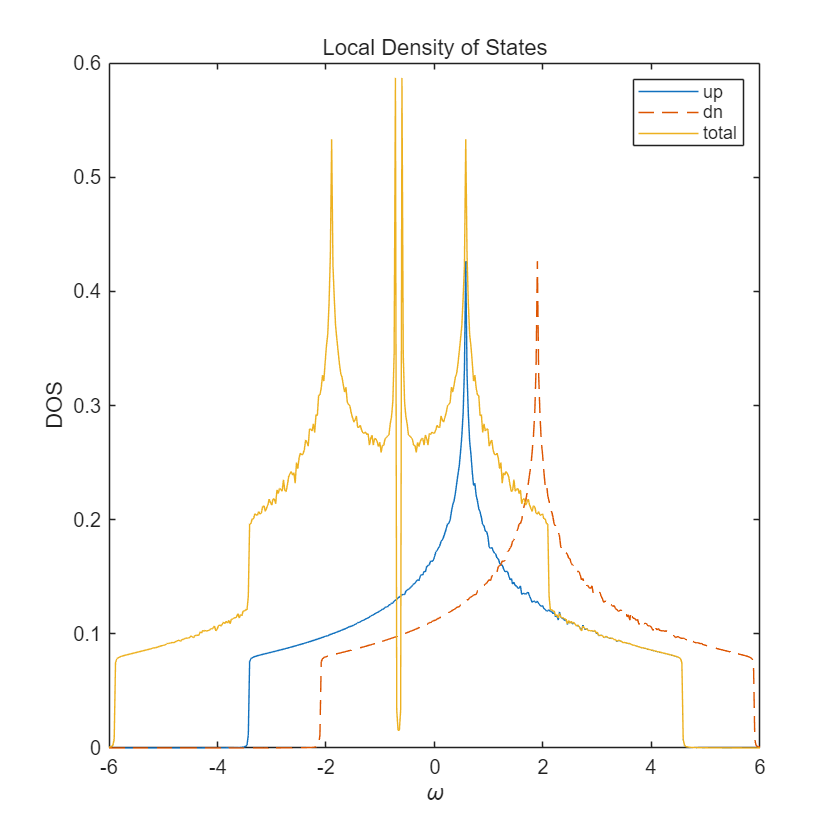


M = 500;
W0 = -6;
Wf = 6;
Wd = (Wf - W0) / M;
MT = linspace(W0, Wf, M+1);
Mup = zeros(1, M+1);
Mdn = zeros(1, M+1);
Me = zeros(1, M+1);

for i = 1:M+1
    w = MT(i);
    Mup(i) = Ldos_up(x, w, params);
    Mdn(i) = Ldos_dn(x, w, params);
    Me(i) = Ldos(x, w, params);
end

figure(1)
plot(MT, -imag(Mup)/pi, '-', MT, -imag(Mdn)/pi, '--', MT, -imag(Me)/pi);
legend('up', 'dn', 'total');
xlabel('\omega'); ylabel('DOS');
title('Local Density of States');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = F1(A, params)
S = 1/(2*pi)^2;
dd = 1e-6;

nf1 = @(k1, k2) S * (gama(k1, k2).^2) ./ (2 * sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd)) ...
    .* (1 - DF(sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) - params.B, params.T) ...
    - DF(sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) + params.B, params.T));
Sp1 = quad2d(nf1, -pi, pi, -pi, pi);
y1 = params.g * Sp1 - 1;

nf2 = @(k1, k2) S * (1 - ek1(k1, k2, A, params) ./ sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) ...
    .* (1 - DF(sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) - params.B, params.T) ...
    - DF(sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) + params.B, params.T)));
Sp2 = quad2d(nf2, -pi, pi, -pi, pi);
y2 = Sp2 - params.nc;

y = [y1; y2];
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = DF(x, T)
y = 1 ./ (exp(x ./ T) + 1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = gama(kx, ky)
y = 1; % Uniform s-wave
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y3 = Ldos(A, w, params)
S = 1/(2*pi)^2;
dd = 0.3e-2;
nf3 = @(k1, k2) S * (1 ./ (w + 1i*dd - (sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) - params.B)) ...
    + 1 ./ (w + 1i*dd - (-sqrt(ek1(k1, k2, A, params).^2 + A(1)^2 * gama(k1, k2).^2 + dd) - params.B)));
y3 = quad2d(nf3, -pi, pi, -pi, pi);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y1 = Ldos_up(A, w, params)
S = 1/(2*pi)^2;
dd = 0.3e-2;
nf1 = @(k1, k2) S * 1 ./ (w + 1i*dd - (ek1(k1, k2, A, params) - params.B) ...
    - A(1)^2 * gama(k1, k2).^2 ./ (w + 1i*dd + (ek1(k1, k2, A, params) + params.B)));
y1 = quad2d(nf1, -pi, pi, -pi, pi);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y1 = Ldos_dn(A, w, params)
S = 1/(2*pi)^2;
dd = 0.3e-2;
nf1 = @(k1, k2) S * 1 ./ (w + 1i*dd - (ek1(k1, k2, A, params) + params.B) ...
    - A(1)^2 * gama(k1, k2).^2 ./ (w + 1i*dd + (ek1(k1, k2, A, params) - params.B)));
y1 = quad2d(nf1, -pi, pi, -pi, pi);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function val = ek1(k1, k2, A, params)
val = -2*params.t*(cos(k1)+cos(k2)) - 4*params.t1*cos(k1).*cos(k2) ...
    - 4*params.t2*((cos(k1)).^2 + (cos(k2)).^2 - 1) - A(2);
end